# **Modello del Problema Chimico "Oregonator"**

Il seguente problema descrive il comportamento del problema chimico "Oregonator" descritto da un sistema di equazioni differenziali che modellano reazioni chimiche dovute a tre sostanze. Queste dopo un periodo di inattività, presentano oscillazioni in cui cambia struttura e colore.

Il sistema di equazioni differenziali è un problema ***"Stiff"*** ed è risolvibile attraverso gli strumenti messi a disposizione dal Matlab. Uno strumento che ci consente la risoluzione è ***"ode15s" ***. In questo documento il problema viene risolto e vengono proposti dei grafici in funzione dei parametri di uscita e in scala logaritmica che descrivono il comportamento di questo fenomeno.

### Modello Matematico del Problema

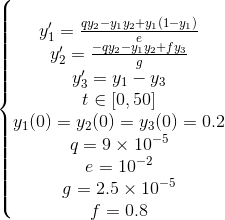

### Risoluzione del Modello

In questa sezione proponiamo un metodo di risoluzione del modello attraverso le routine del MATLAB ***"ode45, ode15s e odeset"*** , viene calcolato il modello di equazioni differenziali sopra descritto. In particolare la routine ***"odeset" ***permette di specificare la "Tolleranza Relativa e Assoluta" di errore utilizzata ai fini della precisione del risultato.

Per completezza richiamiamo uno script appositamente creato che effettua i calcoli sopra descritti.

Risolve_Oregonator()

[ODE45],Tempo: 3.431438e+07 , Numero di punti: 1402461
[ODE15s],Tempo: 8.859908e+04 , Numero di punti: 3715


### Grafico dei Tempi di Risposta: Uso di Plot

Una volta calcolati i tempi di risposta e le soluzioni attraverso le due routine del MATLAB, mostriamo ora un confronto dei due metodi attraverso un grafico

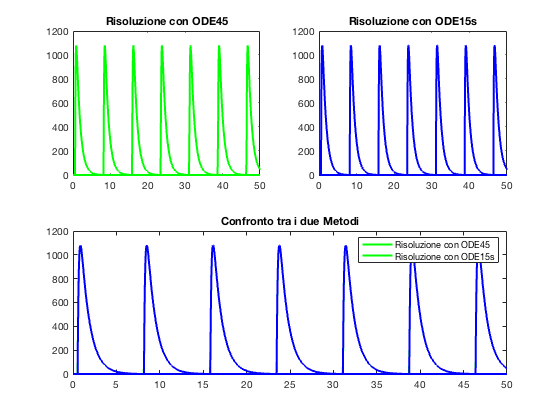

figure();
subplot(2,2,1)
plot(tempo45,y45,'g','LineWidth',2)
title('Risoluzione con ODE45');
subplot(2,2,2)
plot(tempo15s,y15s,'-b','LineWidth',2)
title('Risoluzione con ODE15s');
subplot(2,2,[3,4])
plot(tempo45,y45,'g',tempo15s,y15s,'-b','LineWidth',2)
legend('Risoluzione con ODE45','Risoluzione con ODE15s')
title('Confronto tra i due Metodi');

### Grafico dei Tempi di Risposta: Uso di Semilog

In contrapposizione all'uso di Plot, mostriamo lo stesso risultato con l'ausilio di Semilog

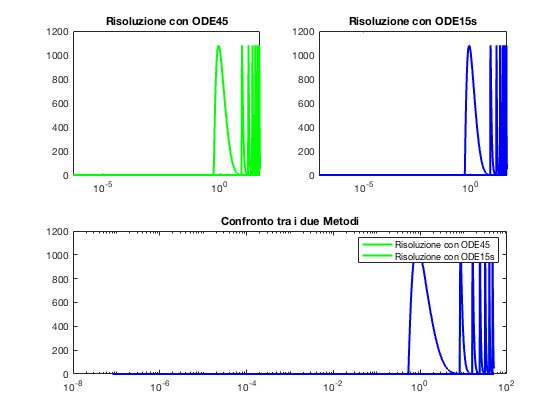

figure();
subplot(2,2,1)
semilogx(tempo45,y45,'g','LineWidth',2)
title('Risoluzione con ODE45');
subplot(2,2,2)
semilogx(tempo15s,y15s,'-b','LineWidth',2)
title('Risoluzione con ODE15s');
subplot(2,2,[3,4])
semilogx(tempo45,y45,'g',tempo15s,y15s,'-b','LineWidth',2)
legend('Risoluzione con ODE45','Risoluzione con ODE15s')
title('Confronto tra i due Metodi');